# EJERCICIO 1a

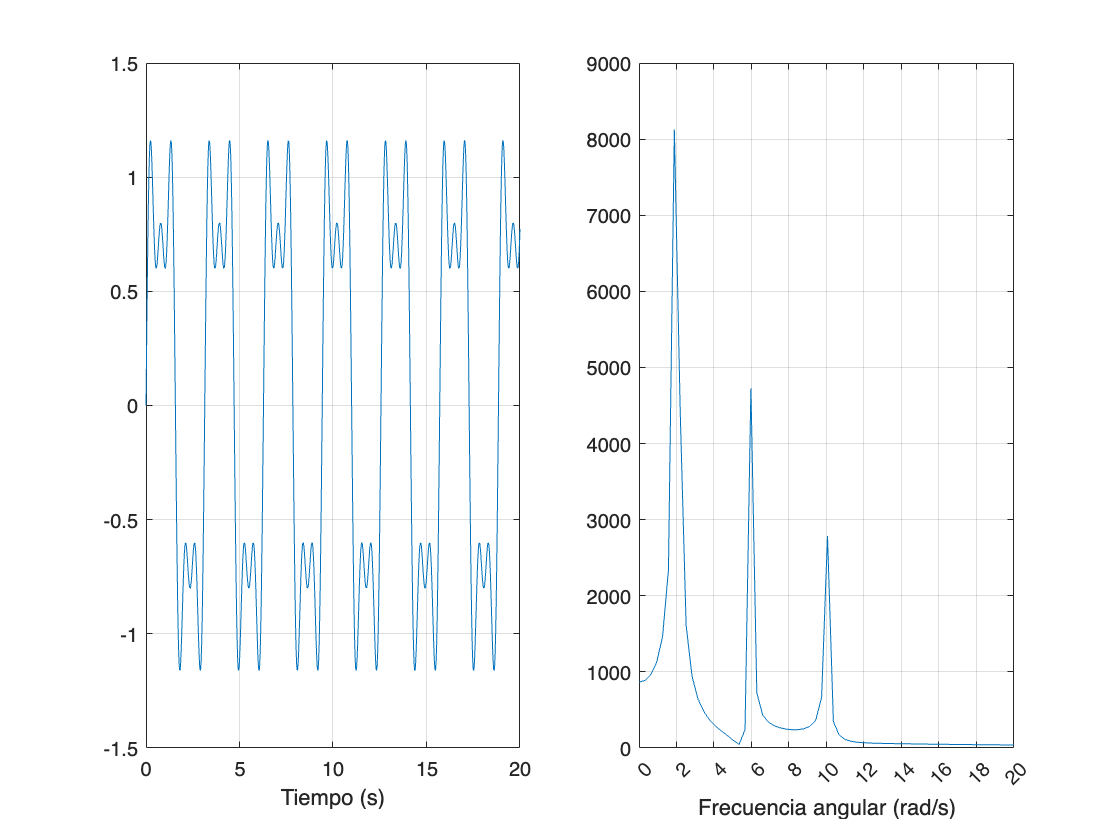

% Señal (en tiempo y en frecuencia)
w = 2;
L = 20001; % 20001 para incluir el 0 y 1 que Ts sea 0,001s por ejemplo
t = linspace(0,20,L);
Ts = 20/(L-1); %0,001
Fs = 1/Ts; %500
yin = sin(w*t) + 0.5*sin(3*w*t) + 0.3*sin(5*w*t);

Y = fft(yin);
f = linspace(0,Fs,L);

subplot(1,2,1);
plot(t, yin)
xlabel('Tiempo (s)')
grid("on");

subplot(1,2,2)
plot(2*pi*f,abs(Y))
xlim([0,20])
xticks(linspace(0,20,11))
xlabel('Frecuencia angular (rad/s)')
grid("on");

## EJERCICIO 1b

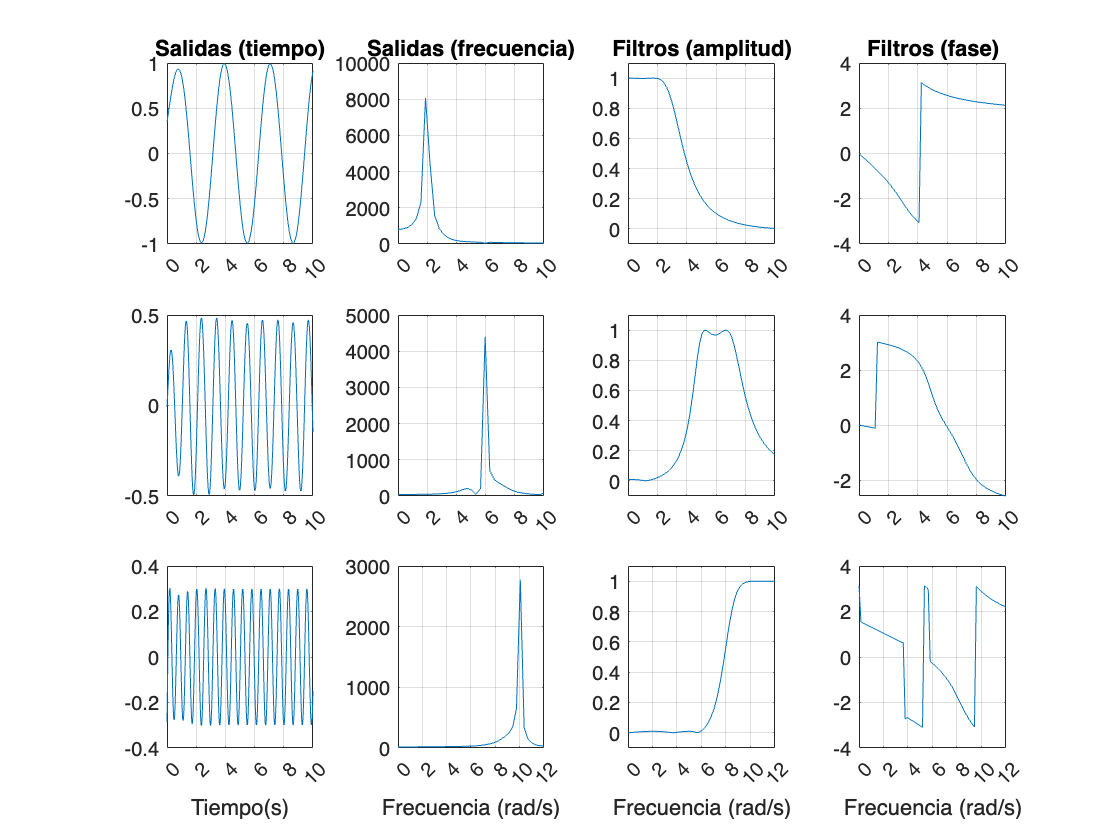

ws = 2*pi*Fs;
w = linspace(0,ws,L);

% 1ª COMPONENTE CON FILTRO ELÍPTICO
n = 3;
wc = 2;
wc_norm = wc/(2*pi*Fs/2);
[num,den] = butter(n, wc_norm, "low", "z"); %wc entre 0 y 1, siendo 1 es wc/2
alfap = 0.3; %Menor que 1 dB
alfas = 30; %Entre 20 y 40 dB
[num,den] = ellip(n, alfap, alfas, wc_norm, "low", "z");
yout1 = filtfilt(num, den, yin);
YOUT1 = fft(yout1); % Devuelve YOUT para L/2 valores entre 0 y Fs/2

% Respuesta en frecuencia del filtro
[Hw1] = freqz(num, den, w*(pi/ws));

posiciones = [1,2,3,4];
limitesx = [0,10];
dibujar(t,yout1,f,YOUT1,w/2,Hw1,posiciones,limitesx)



% 2ª COMPONENTE CON FILTRO CHEBYSHEV 1
n = 2;
wc = [5,7];
wc_norm = wc/(2*pi*Fs/2);
alfap = 0.3;
[num,den] = cheby1(n, alfap, wc_norm, "bandpass", "z");
yout2 = filtfilt(num, den, yin);
YOUT2 = fft(yout2); % Devuelve YOUT para L/2 valores entre 0 y Fs/2

% Respuesta en frecuencia del filtro
[Hw2] = freqz(num, den, w*(pi/ws));

posiciones = [5,6,7,8];
limitesx = [0,10];
dibujar(t,yout2,f,YOUT2,w/2,Hw2,posiciones,limitesx)



% 3ª COMPONENTE CON FILTRO ELÍPTICO
n = 5;
wc = 10;
wc_norm = wc/(2*pi*Fs/2);
alfap = 0.3;
alfas = 30;
[num,den] = ellip(n, alfap, alfas, wc_norm, "high", "z");
yout3 = filtfilt(num, den, yin);
YOUT3 = fft(yout3); % Devuelve YOUT para L/2 valores entre 0 y Fs/2

% Respuesta en frecuencia del filtro
[Hw3] = freqz(num, den, w*(pi/ws));

posiciones = [9,10,11,12];
limitesx = [0,12];
dibujar(t,yout3,f,YOUT3,w/2,Hw3,posiciones,limitesx)

## EJERCICIO 1c

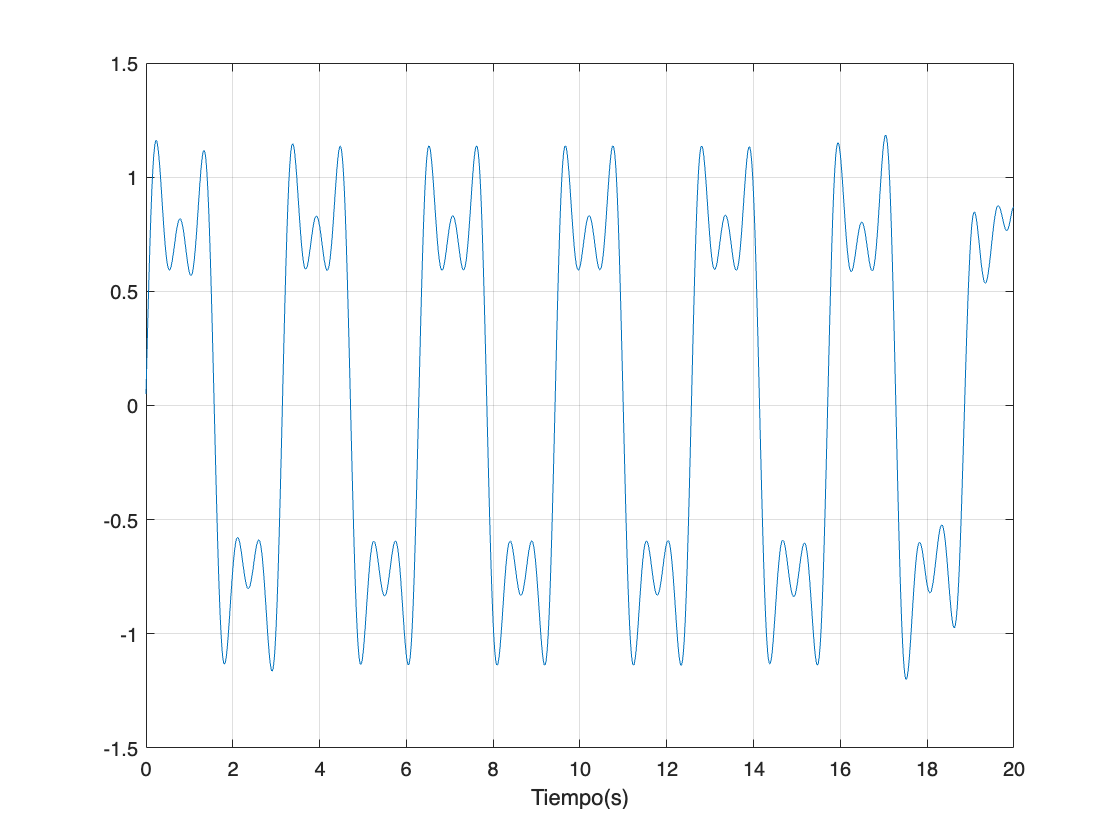

clf
y_rec = yout1+yout2+yout3;
plot(t,y_rec)
xlabel('Tiempo(s)')
grid();

## EJERCICIO 2a

clf
audios = ["mel1.wav", "mel1_noise.wav"];
for i = 1:2
    [x, Fs] = audioread(audios(i));
    %sound(x, Fs);
    %pause(length(x)/Fs);
    L = length(x);
    X = fft(x);
    f = linspace(0,Fs,L);
    subplot(1,2,i)
    plot(f,abs(X));
    xlim([0,Fs/4]);
    xlabel('Frecuencia (Hz)');
    xlim([0,4000]);
    grid();
end

## Ejercicio 3 — Filrando ruido con IIR

[sound, fs]=audioread("mel2_note.wav");
spectrogram(sound);

time=0.05;
n=round(time*fs);
period = 1/fs

period = 2.2676e-05

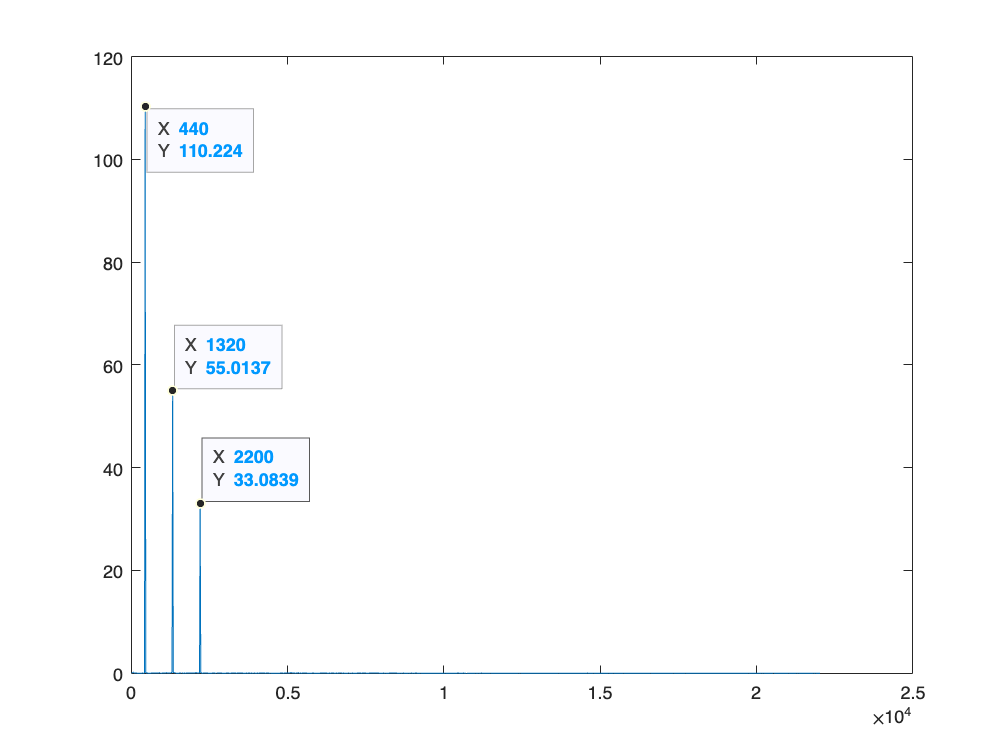

brief_sound=sound(1:n);

% (np.arange(1, n + 1, dtype=int) // 2) / float(n * d)

% THIS IS CORRECT
freqs=(0:(n-1))/n*fs;
points = 1:round(n/2);
sound_fft = fft(brief_sound);
plot(freqs(points),abs(sound_fft(points)));

Index exceeds the number of array elements. Index must not exceed 1024.

Error in yulewalk (line 141)
R  = R(1:nr).*(0.54+0.46*cos(pi*nt/(nr-1)));     % pick NR correlations 

%m=[0 1 1 0.5 1 0];
%f=[0 0.2 0.3 0.5 0.7 1];
% [b,a] = yulewalk(n,f,m);
%[H,w]=freqz(b,a);


% Design notch filter
f=440;

notches=[f, 3*f, 5*f];

w0=notches/(fs/2);
bw = w0/35;
comb=zeros(2,6);
for i=1:3
    [b,a] = iirnotch(w0(i),bw(i));
    comb(i,:)=[b,a];
end

filtered=sosfilt(comb, sound);
audiowrite('mel2_filtered.wav', filtered, fs)%

% play_and_stop(filtered, fs)

function play_and_stop(sound, fs)
   player=audioplayer(sound, fs);
   playblocking(player);
end

function dibujar(t,y1,f,Y1,w,Hw,posiciones,limitesx)
    % Plot de la salida (en tiempo y en frecuencia)
    subplot(3,4,posiciones(1));
    plot(t,y1);
    if posiciones == [1,2,3,4]
        title('Salidas (tiempo)');
    end
    xlim([0,10]);
    xticks(linspace(0,10,6));
    grid("on");
    if posiciones == [9,10,11,12]
        xlabel('Tiempo(s)')
    end
    
    subplot(3,4,posiciones(2))
    plot(2*pi*f, abs(Y1))
    xlim(limitesx)
    xticks(linspace(min(limitesx), max(limitesx), 1+max(limitesx)/2))
    if posiciones == [1,2,3,4]
        title('Salidas (frecuencia)')
    end
    grid("on");
    if posiciones == [9,10,11,12]
        xlabel('Frecuencia (rad/s)')
    end
    
    % Plot del filtro (amplitud y fase)
    subplot(3,4,posiciones(3))
    plot(w, abs(Hw))
    xlim(limitesx)
    xticks(linspace(min(limitesx), max(limitesx), 1+max(limitesx)/2))
    ylim([-0.1, 1.1])
    if posiciones == [1,2,3,4]
        title('Filtros (amplitud)')
    end
    grid("on");
    if posiciones == [9,10,11,12]
        xlabel('Frecuencia (rad/s)')
    end
    
    subplot(3,4,posiciones(4));
    plot(w, angle(Hw));
    xlim(limitesx);
    xticks(linspace(min(limitesx), max(limitesx), 1+max(limitesx)/2));
    if posiciones == [1,2,3,4]
        title('Filtros (fase)')
    end
    grid("on");
    if posiciones == [9,10,11,12]
        xlabel('Frecuencia (rad/s)')
    end
    
    
end


%% Part 3
